Call the ROC script

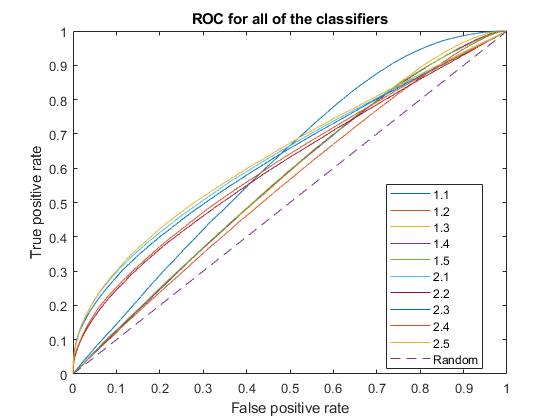

AUC11 =    6.1676e-01


AUC12 =    5.5004e-01


AUC13 =    5.6781e-01


AUC14 =    5.6576e-01


AUC15 =    5.6747e-01


AUC21 =    6.3891e-01


AUC22 =    6.0788e-01


AUC23 =    6.3105e-01


AUC24 =    6.1528e-01


AUC25 =    6.4388e-01


roc_v7_second_op

psame = 0.1360;
N = 6*31;
k = 0:N;

Idea : Choose classifier that has the greatest accuracy in our experiment

falsePosCell = {X11 X12 X13 X14 X15 X21 X22 X23 X24 X25};
truePosCell = {Y11 Y12 Y13 Y14 Y15 Y21 Y22 Y23 Y24 Y25};
thresholdCell = {T11 T12 T13 T14 T15 T21 T22 T23 T24 T25};
selectedPoints = zeros(length(falsePosCell),7); %th_distinguisher, th_bino, accuracy, fpr_bino, tpr_bino, fpr_dist, tpr_dist

%Get the best point for each one of them
for i = 1 : length(falsePosCell)
    fprVector = cell2mat(falsePosCell(i));
    tprVector = cell2mat(truePosCell(i));
    thresholdVector = cell2mat(thresholdCell(i));
    [selectedPoints(i,1), selectedPoints(i,2), selectedPoints(i,3), selectedPoints(i,4), selectedPoints(i,5), selectedPoints(i,6), selectedPoints(i,7)] = getThresholdDistinguisher(fprVector,tprVector,thresholdVector,psame,N);
end
clearvars falsePosCell truePosCell thresholdCell fprVector tprVector thresholdVector

Display thresholds for each classifier, their accuracy and total values for false positive rate and true positive rate

for i = 1 : size(selectedPoints,1)
    fprintf("Classifier %d",i);
    selectedPoints(i,1)
    selectedPoints(i,2)
    selectedPoints(i,3)
    selectedPoints(i,4)
    selectedPoints(i,5)
    selectedPoints(i,6)
    selectedPoints(i,7)
end

Classifier 1

ans =    9.8404e-01


ans =    170


ans =    9.9765e-01


ans =    2.2938e-03


ans =    9.9765e-01


ans =    8.2125e-01


ans =    9.5789e-01


Classifier 2

ans =    9.7438e-01


ans =    175


ans =    8.6527e-01


ans =    1.5433e-01


ans =    8.6527e-01


ans =    9.1164e-01


ans =    9.5640e-01


Classifier 3

ans =    9.9519e-01


ans =    175


ans =    9.5565e-01


ans =    4.9655e-02


ans =    9.5565e-01


ans =    8.9450e-01


ans =    9.6382e-01


Classifier 4

ans =    9.8806e-01


ans =    161


ans =    9.1760e-01


ans =    8.7801e-02


ans =    9.1760e-01


ans =    8.1479e-01


ans =    8.9553e-01


Classifier 5

ans =    9.9024e-01


ans =    153


ans =    9.2395e-01


ans =    8.4053e-02


ans =    9.2395e-01


ans =    7.6577e-01


ans =    8.5868e-01


Classifier 6

ans =    3.5592e-02


ans =     28


ans =    9.9833e-01


ans =    1.5374e-03


ans =    9.9833e-01


ans =    5.8956e-02


ans =    2.3422e-01


Classifier 7

ans =    1.8695e-03


ans =     29


ans =    9.8859e-01


ans =    9.6795e-03


ans =    9.8859e-01


ans =    8.0288e-02


ans =    2.1835e-01


Classifier 8

ans =    1.2356e-03


ans =     27


ans =    9.9703e-01


ans =    2.6267e-03


ans =    9.9703e-01


ans =    5.9774e-02


ans =    2.2159e-01


Classifier 9

ans =    1.7205e-03


ans =     25


ans =    9.9149e-01


ans =    7.6097e-03


ans =    9.9149e-01


ans =    6.1571e-02


ans =    1.9760e-01


Classifier 10

ans =    9.0445e-06


ans =     32


ans =    9.9851e-01


ans =    1.4293e-03


ans =    9.9851e-01


ans =    7.3450e-02


ans =    2.6076e-01


Which is the best classifier

[val,ind] = max(selectedPoints(:,3))

val =    9.9851e-01


ind =     10


Plot binomial distributions for that classifier

ytrue = binopdf(k,N,selectedPoints(ind,7));
prandom = psame * selectedPoints(ind,7) + (1 - psame) * selectedPoints(ind,6)

prandom =    9.8924e-02


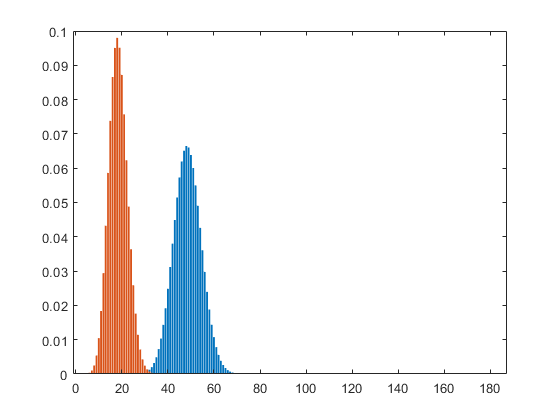

yrandom = binopdf(k,N,prandom);
bar(k,ytrue)
hold on
bar(k,yrandom)
hold off

Which gives us, according to Hanley's explanation

bitErrors = 521*(1-selectedPoints(ind,3))

bitErrors =    7.7767e-01


cost = 0;
n2 = ceil(521/2);
for i = 1 : ceil(bitErrors/2)
    cost = cost + nchoosek(n2,i);
end
cost = cost * 521

cost =       135981


Which is equivalent to 2^ to the 

exponent = log2(double(cost))

exponent =    1.7053e+01


Save results

save('./results_characterization/v7_second_op_3.mat','selectedPoints');